**Divergent Starting (-1.8,-1.4)**

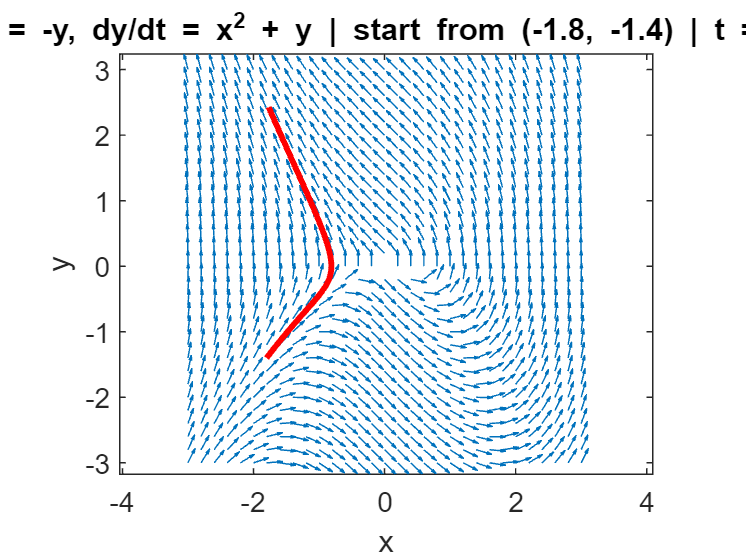

% Range
x = -3:0.2:3; 
y = -3:0.2:3;

% Grid
[X, Y] = meshgrid(x, y);

% System 
U = -Y;
V = X.^2 + Y;

% Normalize arrow length
arrow_length = sqrt(U.^2 + V.^2);
U = U ./ arrow_length;
V = V ./ arrow_length;

% Plot
figure
quiver(X, Y, U, V)
hold on

% Initial conditions
x0 = -1.8;
y0 = -1.4;

% Time span
tspan = [0, 3];

% System Definition
system = @(t, Y) [-Y(2); Y(1)^2 + Y(2)];

% ODE45 method
[~, Y] = ode45(system, tspan, [x0, y0]);

% Path
plot(Y(:,1), Y(:,2), 'r', 'LineWidth', 2)

axis equal

% Styling
title('dx/dt = -y, dy/dt = x^2 + y | start from (-1.8, -1.4) | t = [0, 3]')
xlabel('x')
ylabel('y')

hold off

**Divergent Starting (-1.7,-1.4)**

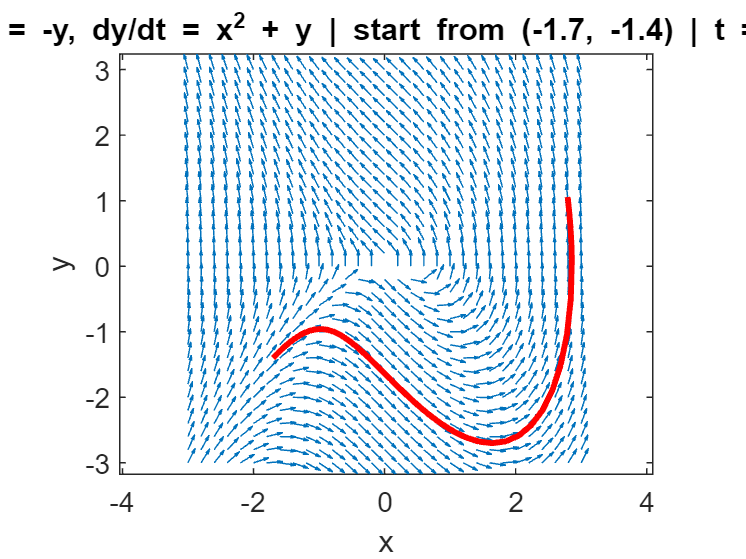

% Range
x = -3:0.2:3; 
y = -3:0.2:3;

% Grid
[X, Y] = meshgrid(x, y);

% System 
U = -Y;
V = X.^2 + Y;

% Normalize arrow length
arrow_length = sqrt(U.^2 + V.^2);
U = U ./ arrow_length;
V = V ./ arrow_length;

% Plot
figure
quiver(X, Y, U, V)
hold on

% Initial conditions
x0 = -1.7;
y0 = -1.4;

% Time span
tspan = [0, 3];

% System Definition
system = @(t, Y) [-Y(2); Y(1)^2 + Y(2)];

% ODE45 method
[~, Y] = ode45(system, tspan, [x0, y0]);

% Path
plot(Y(:,1), Y(:,2), 'r', 'LineWidth', 2)

axis equal

% Styling
title('dx/dt = -y, dy/dt = x^2 + y | start from (-1.7, -1.4) | t = [0, 3]')
xlabel('x')
ylabel('y')

hold off

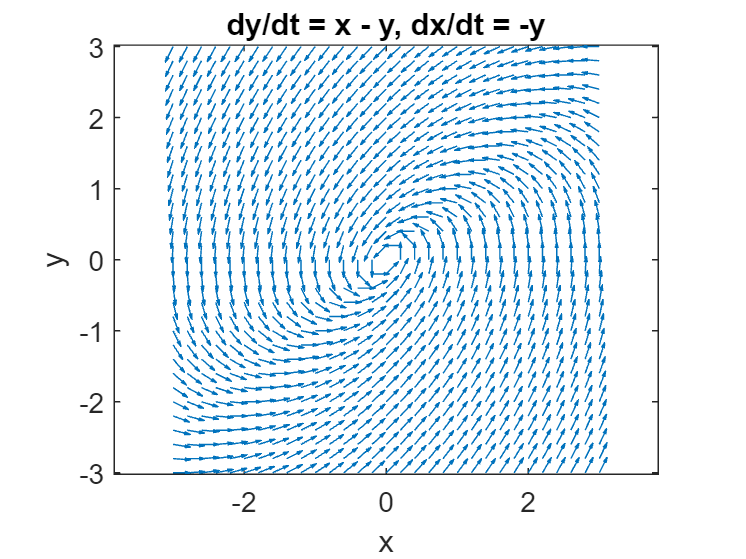

x = -3:0.2:3; 
y = -3:0.2:3;


[X, Y] = meshgrid(x, y);

U = -Y;
V = X - Y;

arrow_length = sqrt(U.^2 + V.^2);
U = U ./ arrow_length;
V = V ./ arrow_length;

figure
quiver(X, Y, U, V)
hold on

axis equal

title('dy/dt = x - y, dx/dt = -y')
xlabel('x')
ylabel('y')

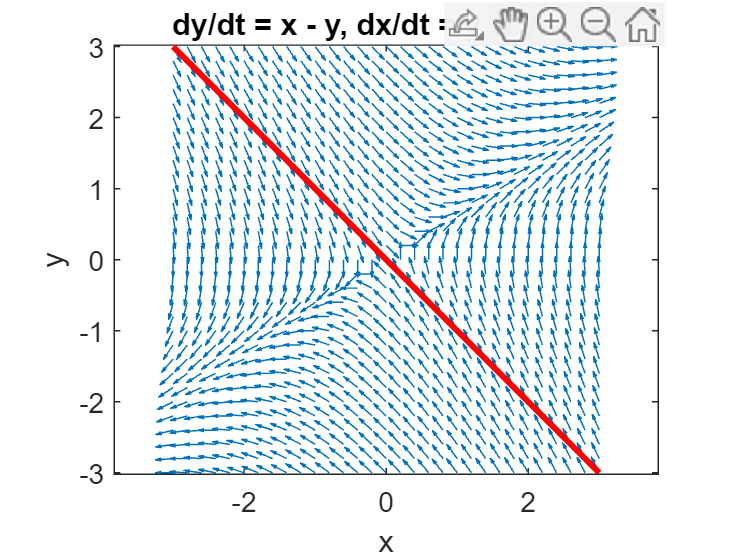

x = -3:0.2:3; 
y = -3:0.2:3;


[X, Y] = meshgrid(x, y);

U = Y;
V = X - Y;

arrow_length = sqrt(U.^2 + V.^2);
U = U ./ arrow_length;
V = V ./ arrow_length;

figure
quiver(X, Y, U, V)
hold on

plot(x, -x, 'r', 'LineWidth', 2);
hold off

axis equal

title('dy/dt = x - y, dx/dt = y & y = -x')
xlabel('x')
ylabel('y')